clear; close all; clc;

Plot settings

figureTitles = true;

cMap=[0.6*ones(256,2), linspace(1, 0, 256)'];
fontSize=15;
markerSize=20;

blue   = [0, 0.4470, 0.7410];  % "#0072BD"
cyan  = [0.3010, 0.7450, 0.9330];  % "#4DBEEE"
red = [0.8500, 0.3250, 0.0980];  % "#D95319"

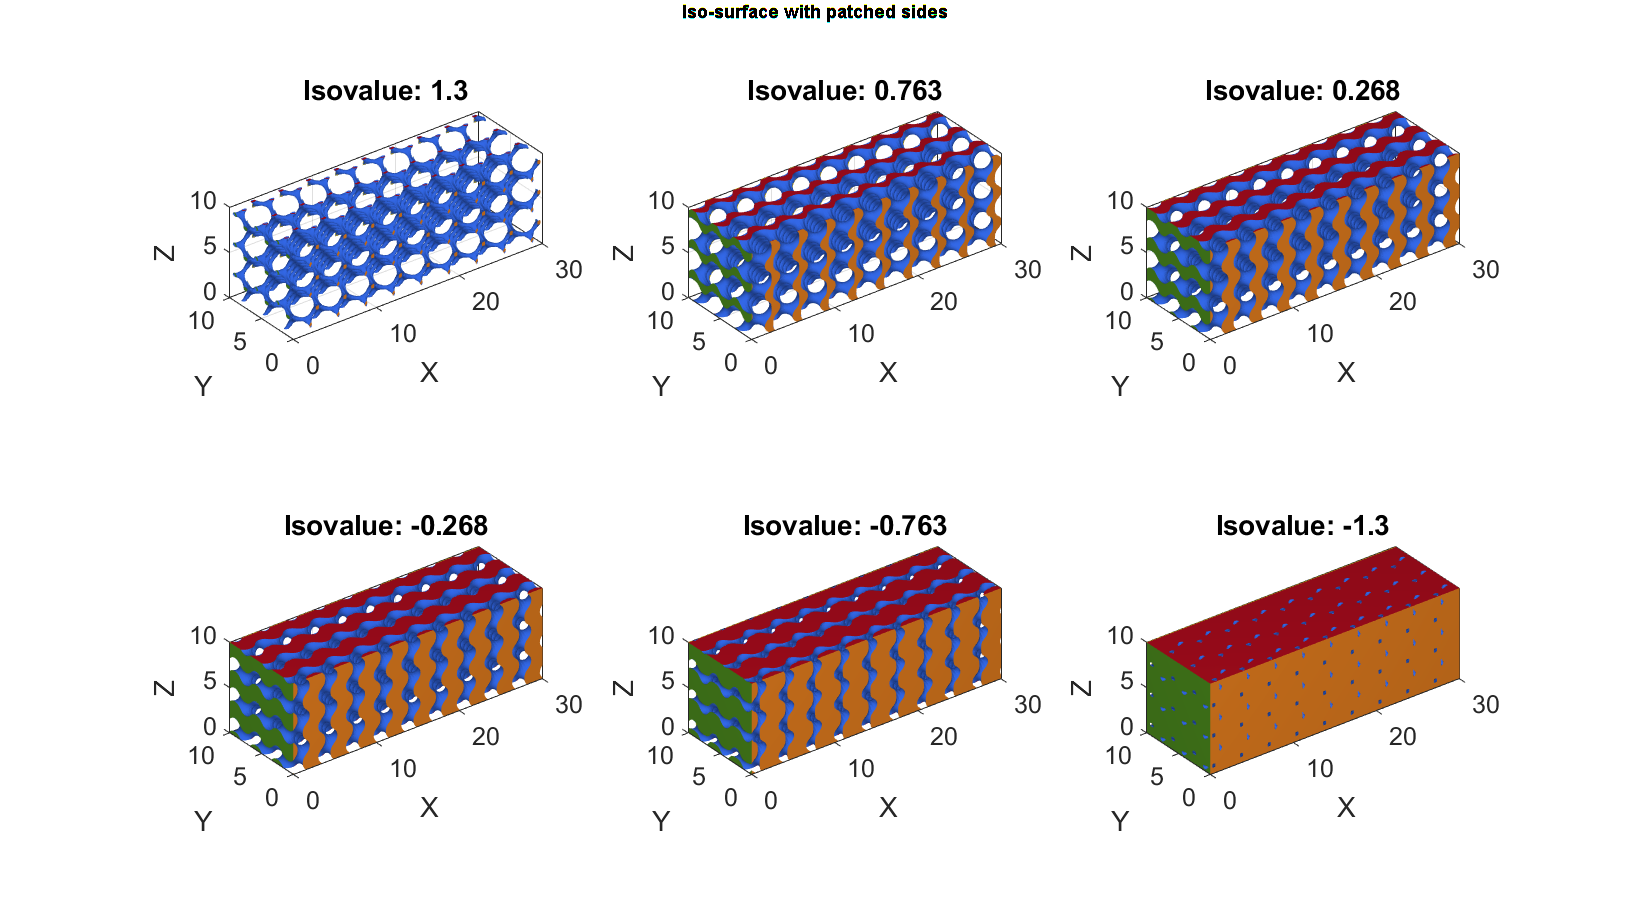

count = 1; % initialise

nCols = 3;
nRows = 2;
linspace_steps = 64;

fig1 = cFigure; fig2 = cFigure; fig3 = cFigure; fig4 = cFigure; fig5 = cFigure;
fig6 = cFigure; fig7 = cFigure; fig8 = cFigure; fig9 = cFigure; fig10 = cFigure;

original_points = linspace(1.3, -1.3, linspace_steps);
selected_idx = round(linspace(1, linspace_steps, nCols * nRows)); % Select 6 evenly spaced indices

for i = original_points(selected_idx)

defaultFolder = fullfile('D:','TechnicalReport','LatticeProperties_LinearFinal'); % Changed to external hard drive
savePath = fullfile(defaultFolder,sprintf('%.5g_Lattice_Density',i));
matlabPath = fullfile(savePath,'simulation_results.mat');

load(matlabPath);

f = resultStruct.f; v = resultStruct.v; c = resultStruct.c;

figure(fig1);
subplot(nRows, nCols, count);
title(sprintf('Isovalue: %.3g',resultStruct.level_set));

if figureTitles
    gtitle('Iso-surface with patched sides');
end

% title('Face labelling');
hp1 = gpatch(f,v,c,'none', 1); 
hp1.FaceColor = 'flat';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

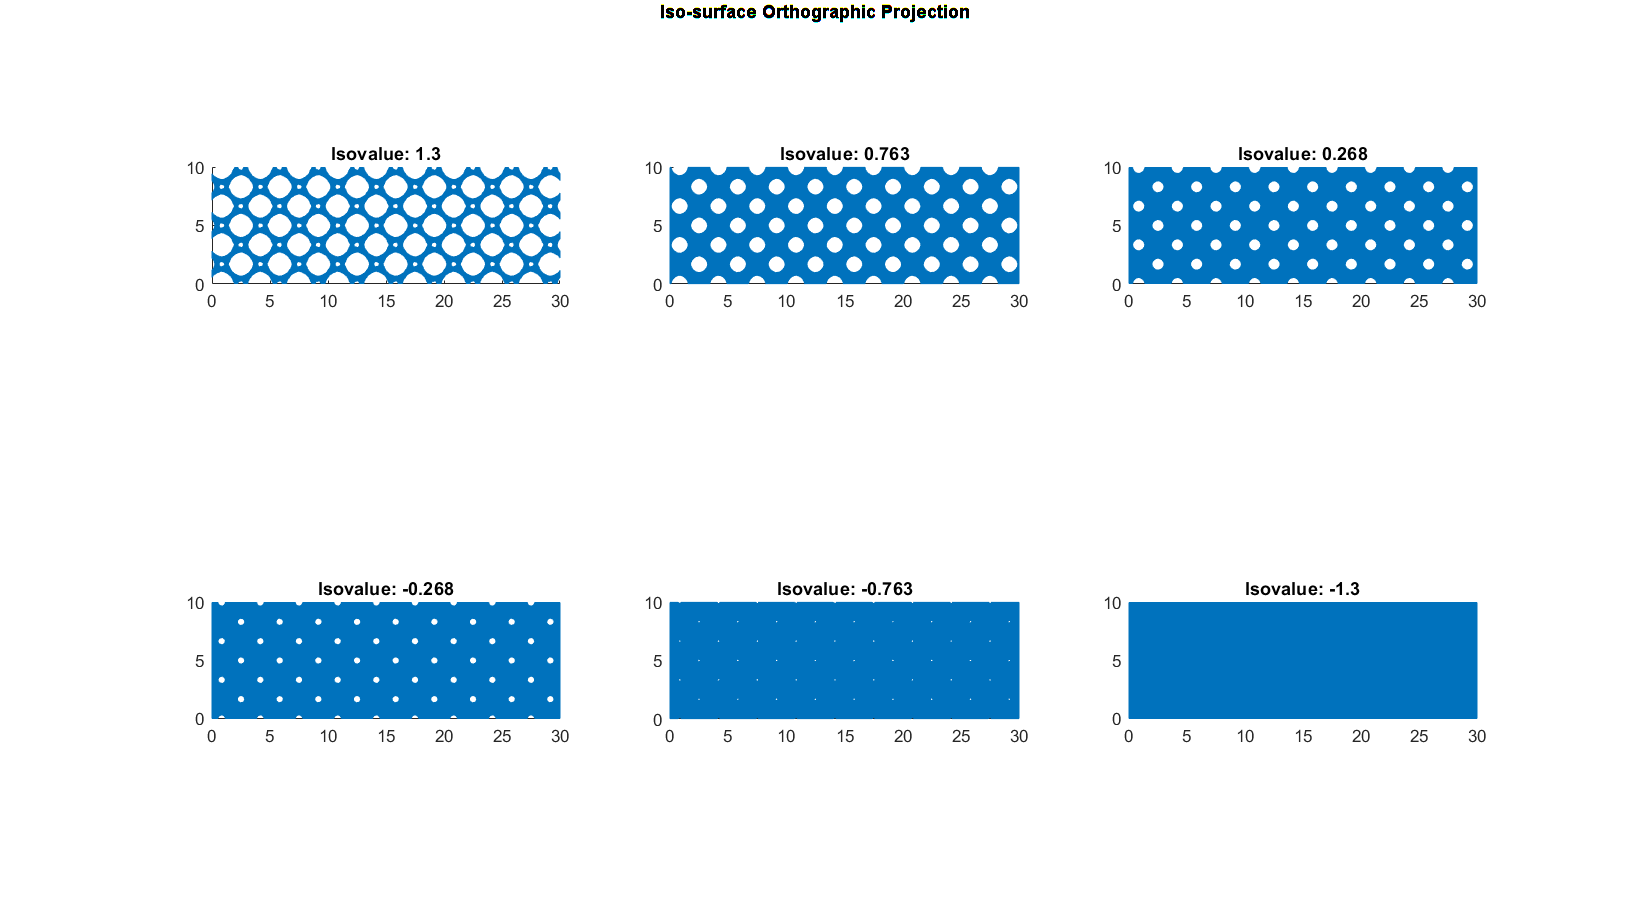

figure(fig2);
subplot(nRows, nCols, count);
title(sprintf('Isovalue: %.3g',resultStruct.level_set));

if figureTitles
    gtitle('Iso-surface Orthographic Projection');
end

% title('Orthographic Projection');
% Create the patch with uniform color
hp2 = gpatch(f, v, 'none', 1);
hp2.FaceColor = [0 0.4470 0.7410];
hp2.EdgeColor = [0 0.4470 0.7410];
axis equal;
xlim([min(v(:,1)), max(v(:,1))]) % Adjust x-axis limits to your data range
ylim([min(v(:,2)), max(v(:,2))]) % Adjust y-axis limits to your data range

figure(fig3);
subplot(nRows, nCols, count);
title(sprintf('Isovalue: %.3g',resultStruct.level_set));

if figureTitles
    gtitle('Iso-surface generation');
end

hp3 = gpatch(f,v,c,'none', 1); 
hp3.FaceColor = [0 0.4470 0.7410];
% hp3.EdgeColor = 'k';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

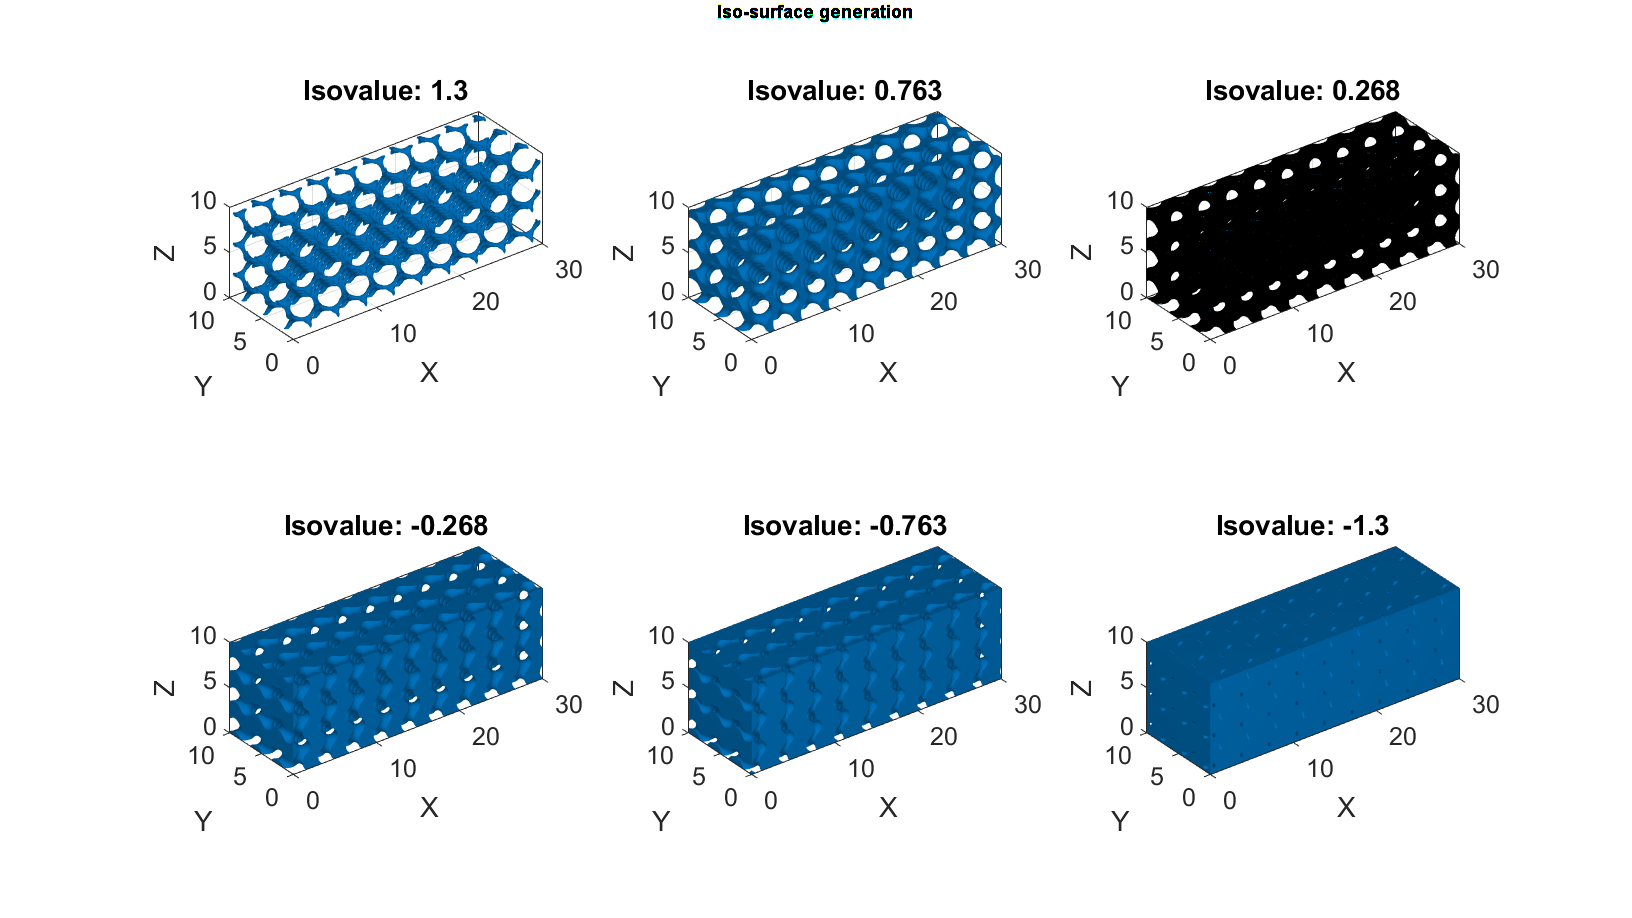

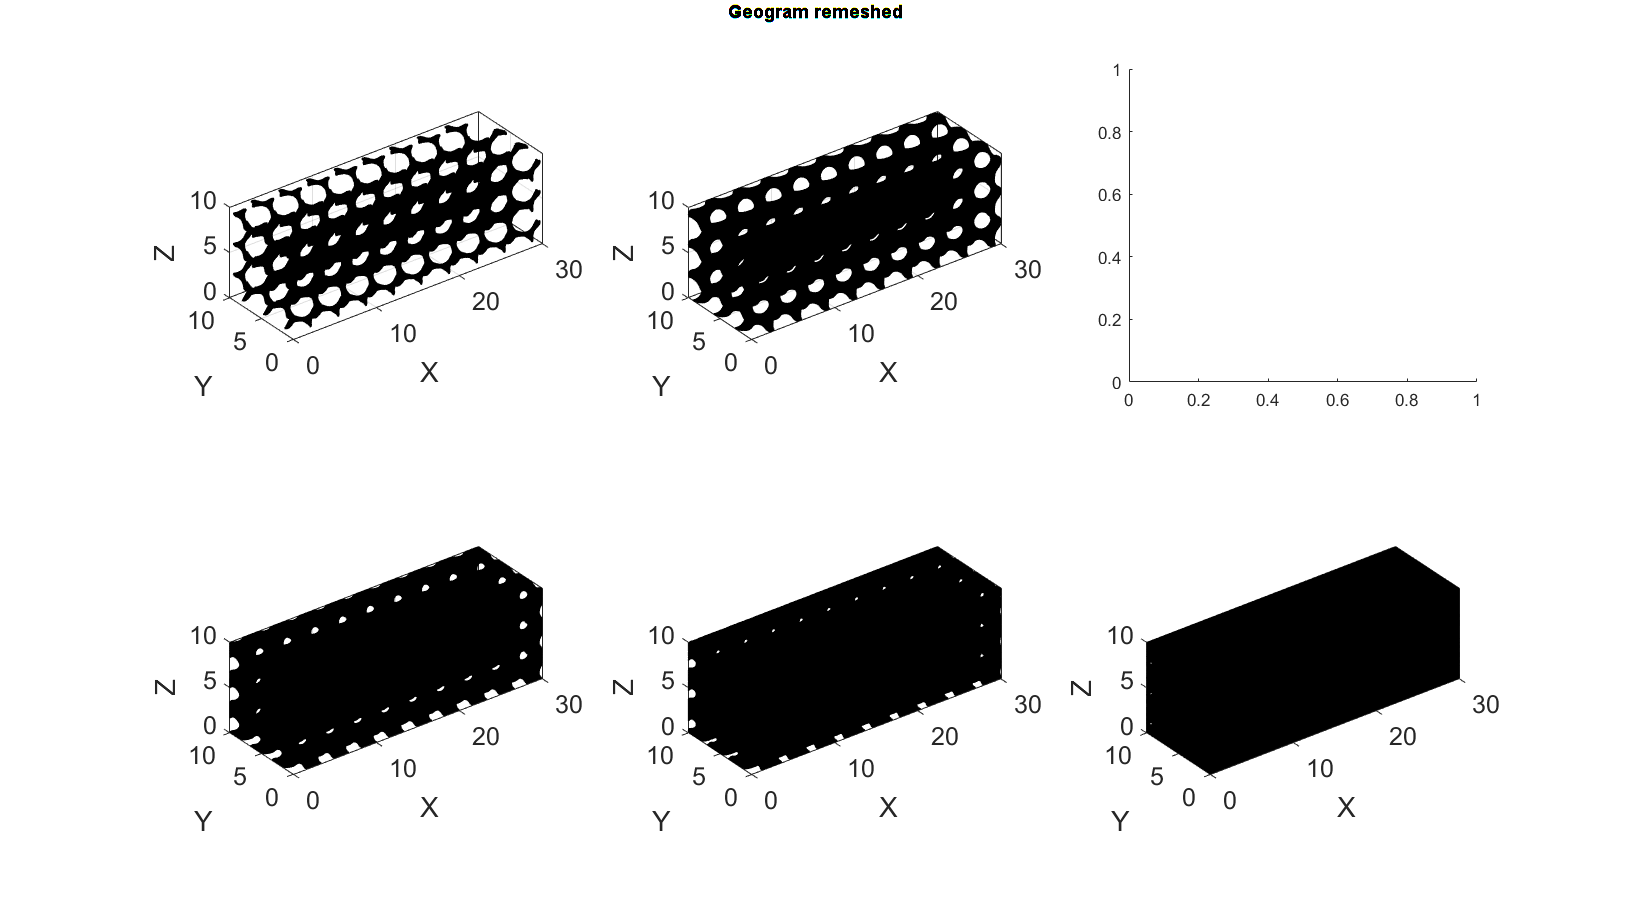

F = resultStruct.F; V = resultStruct.V;
figure(fig4);
subplot(nRows, nCols, count); hold on;

if figureTitles
    gtitle('Geogram remeshed');
end

gpatch(F,V,'w','k',1);
axisGeom(gca,fontSize);
camlight headlight;

x_length = resultStruct.lattice.x_length;
% xlim([1/3 + 1, 2 + 1/3] * x_length);
% ylim([1, 2] * x_length);

meshOutput = resultStruct.meshOutput;
% meshView(meshOutput);
Fb=meshOutput.facesBoundary;
V=meshOutput.nodes;

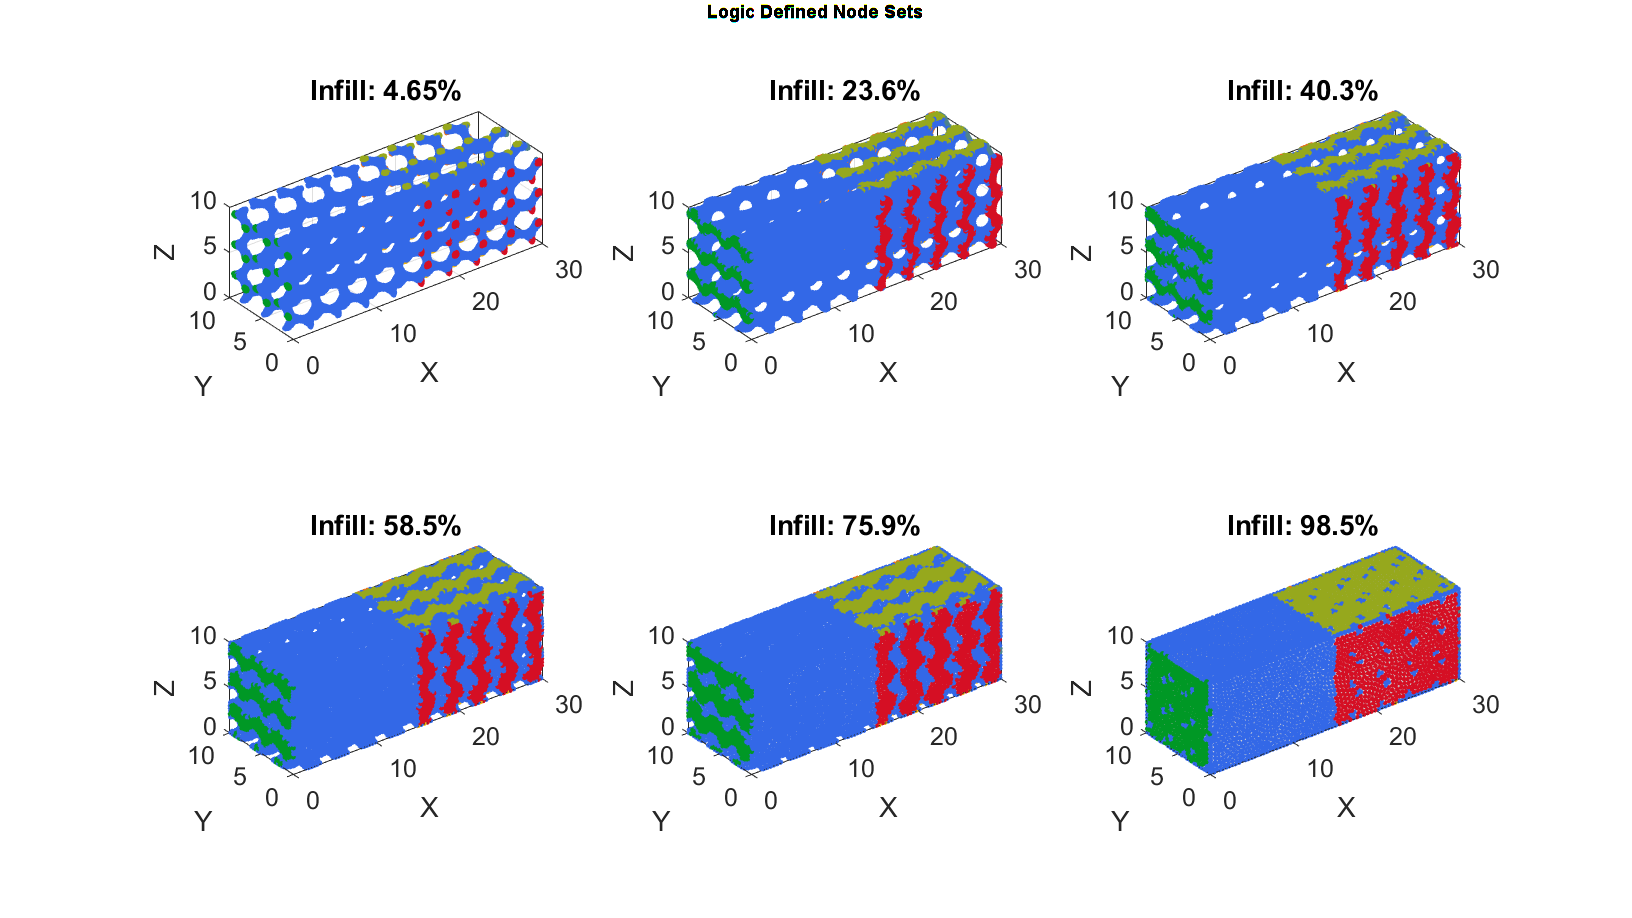

C_vertex = resultStruct.C_vertex;

figure(fig5);
subplot(nRows, nCols, count);

title(sprintf('Infill: %.3g%%',resultStruct.infill_percentage));

if figureTitles
    gtitle('Logic Defined Node Sets');
end

xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;

gpatch(Fb,V,'w','none',1);
scatterV(V,10,C_vertex,'filled');

axisGeom(gca,fontSize);
colormap gjet; % icolorbar;
camlight headlight;

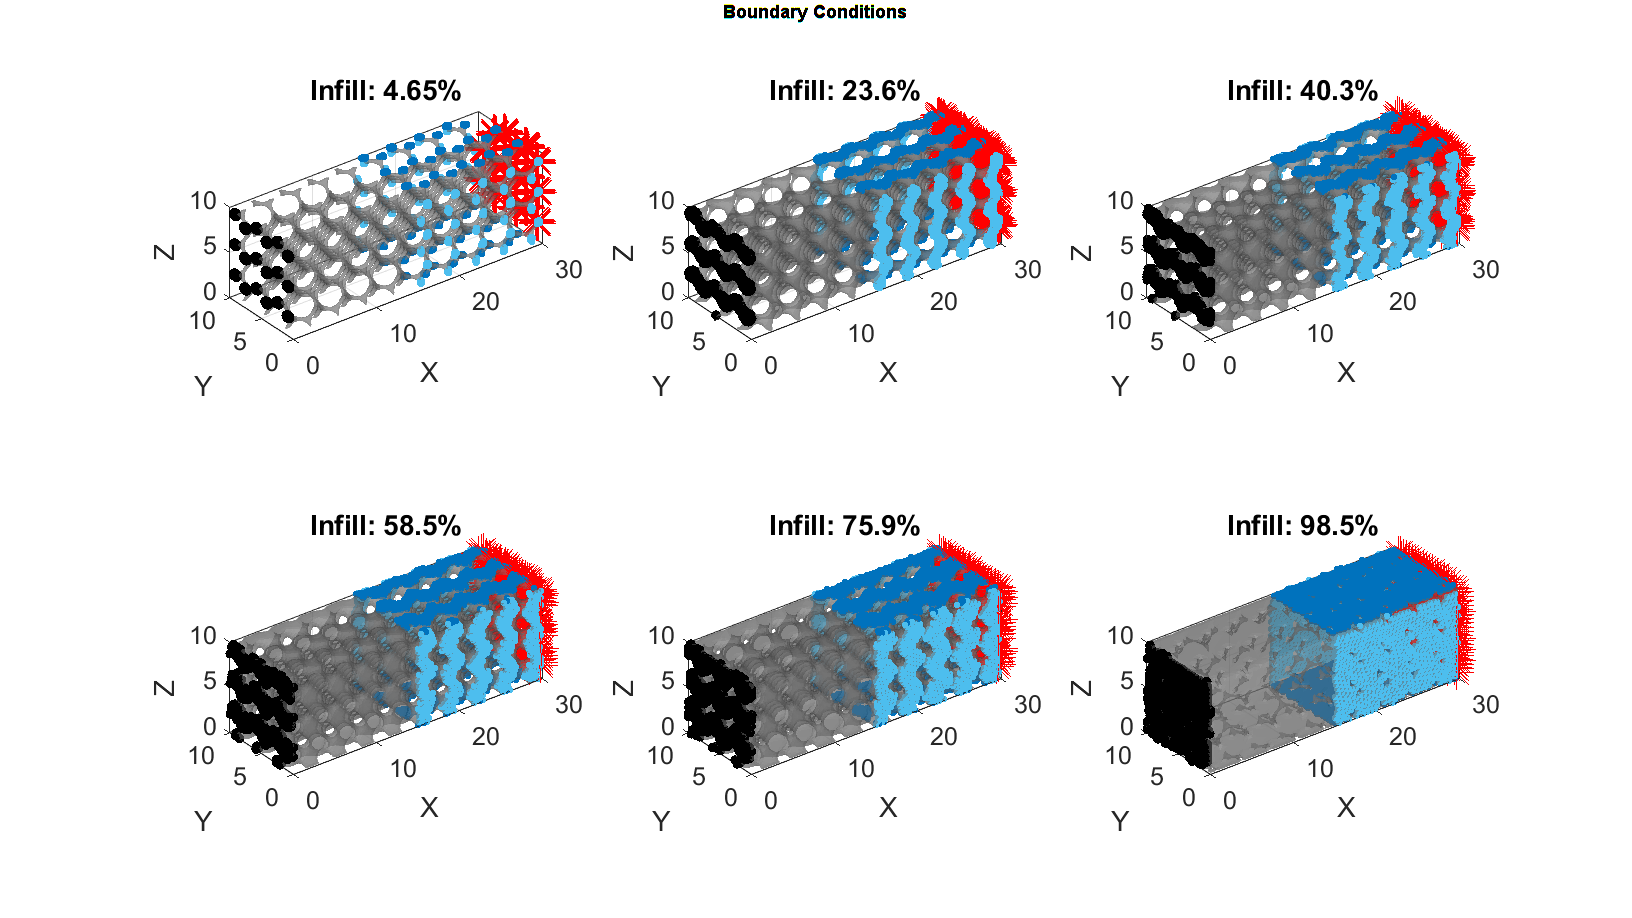

bcEncastreList = resultStruct.bcSets.bcEncastreList;
bcLoadList = resultStruct.bcSets.bcLoadList;
bcTrackY = resultStruct.bcSets.bcTrackY;
bcTrackZ = resultStruct.bcSets.bcTrackZ;

figure(fig6);
test = subplot(nRows, nCols, count);
title(sprintf('Infill: %.3g%%',resultStruct.infill_percentage));

if figureTitles
    gtitle('Boundary Conditions');
end

xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;
gpatch(Fb,V,'kw','none',0.5);

test(1)=plotV(V(bcEncastreList,:),'r*','MarkerSize',markerSize);
test(2)=plotV(V(bcLoadList,:),'k.','MarkerSize',markerSize);
test(3)=plotV(V(bcTrackZ,:),'.','MarkerSize',markerSize/2, 'MarkerEdgeColor', blue);
test(4)=plotV(V(bcTrackY,:),'c.','MarkerSize',markerSize/2, 'MarkerEdgeColor', cyan);
% legend(test,{'BC Load','BC Encastre','BC Track Z','BC Track Y'});

axisGeom(gca,fontSize);
camlight headlight;

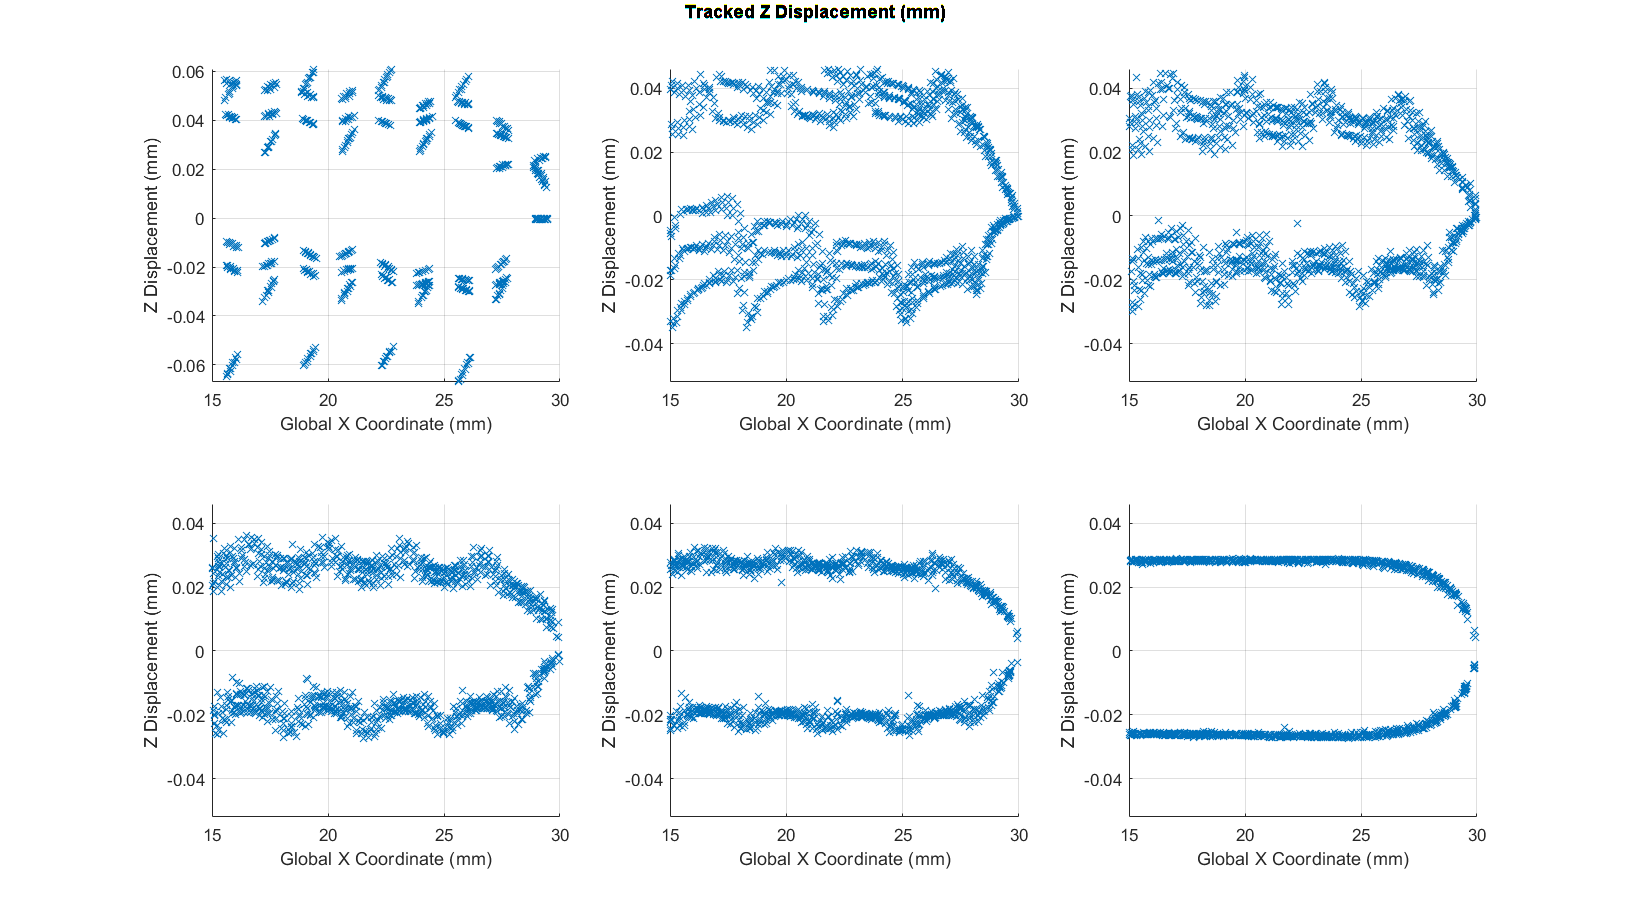

figure(fig7);
subplot(nRows, nCols, count);

if figureTitles
    gtitle('Tracked Z Displacement (mm)')
end

title(sprintf('Infill: %.3g%%',resultStruct.infill_percentage));

xz = resultStruct.xz; Uz = resultStruct.Uz;
scatter(xz, Uz, 'x', 'MarkerEdgeColor', blue);

xlabel('Global X Coordinate (mm)');
ylabel('Z Displacement (mm)');
grid on;

if count == 1
    maxY = max(Uz);
    minY = min(Uz);
    
    ceilFactor = 1e-3;
    maxY = ceil(maxY / ceilFactor) * ceilFactor;
    minY = floor(minY / ceilFactor) * ceilFactor;
end

ylim([minY maxY]);

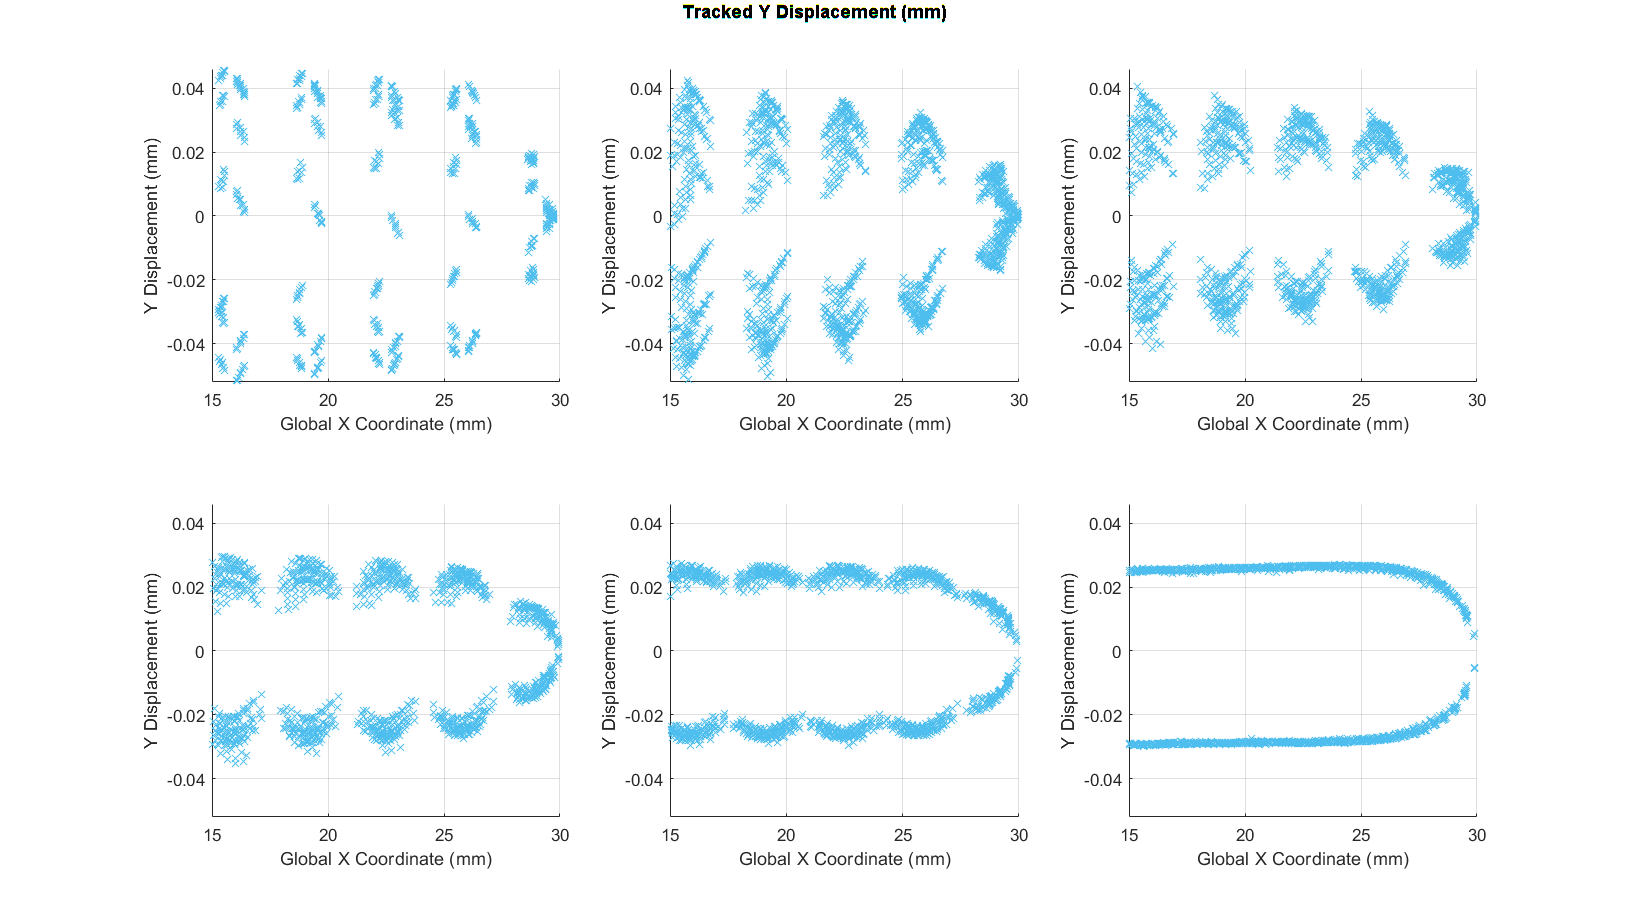

figure(fig8);
subplot(nRows, nCols, count);

if figureTitles
    gtitle('Tracked Y Displacement (mm)')
end

title(sprintf('Infill: %.3g%%',resultStruct.infill_percentage));

xy = resultStruct.xy; Uy = resultStruct.Uy;
scatter(xy, Uy, 'x', 'MarkerEdgeColor', cyan);

xlabel('Global X Coordinate (mm)');
ylabel('Y Displacement (mm)');
grid on;

if count == 1
    maxY = max(Uy);
    minY = min(Uy);

    ceilFactor = 1e-3;
    maxY = ceil(maxY / ceilFactor) * ceilFactor;
    minY = floor(minY / ceilFactor) * ceilFactor;
end

ylim([minY maxY]);

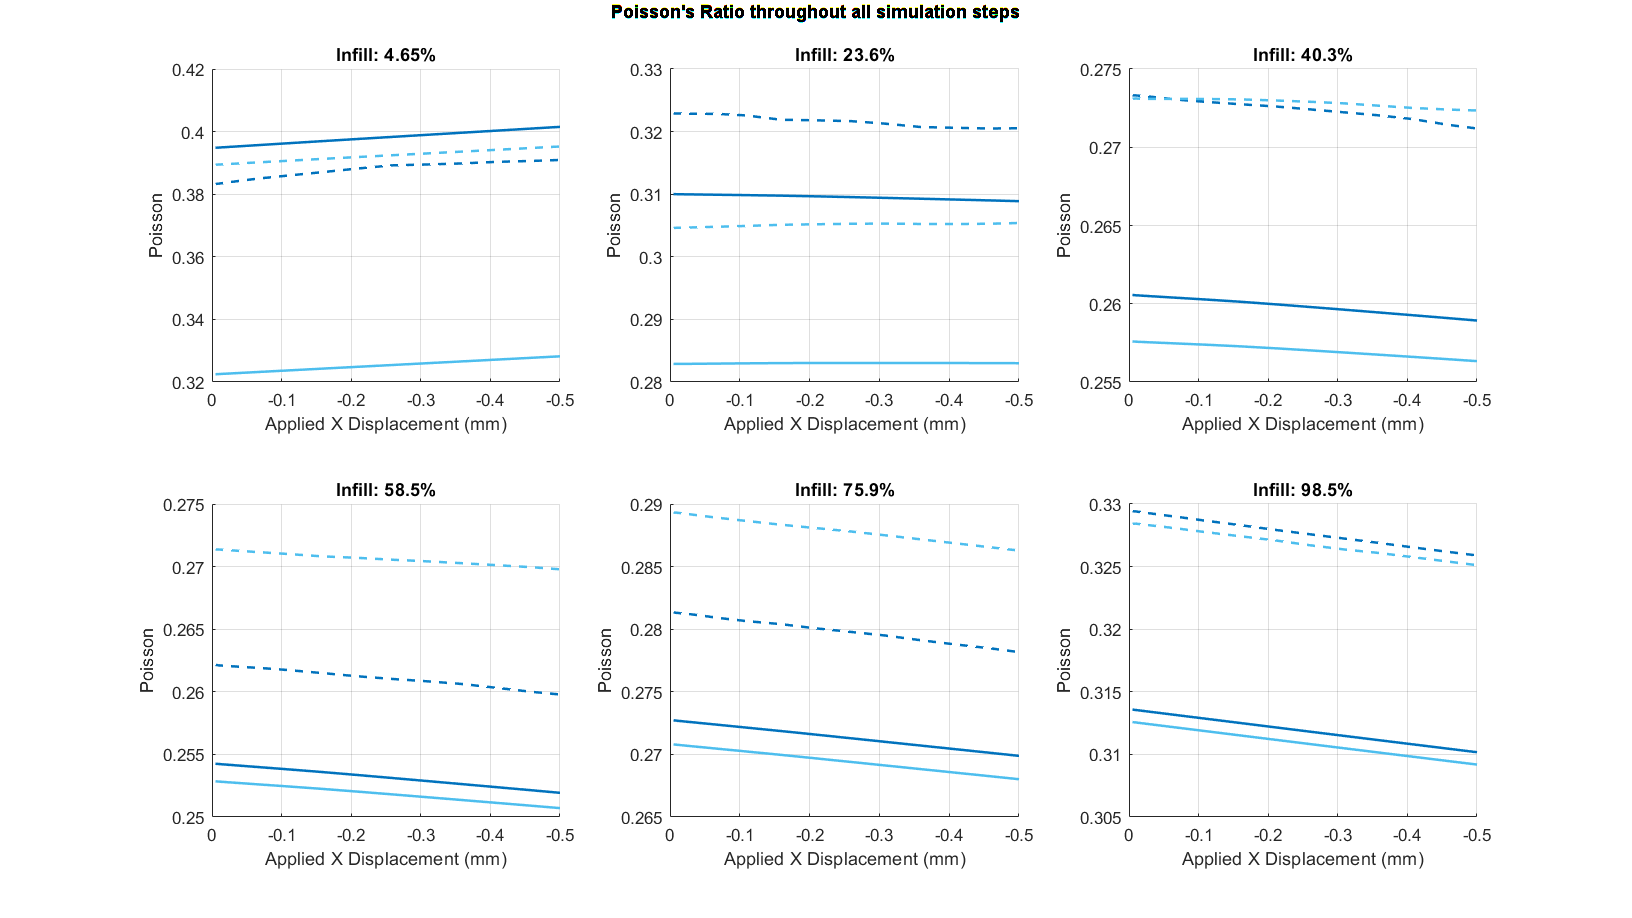

U_x = resultStruct.U_x;
poisson_xz_mean = resultStruct.poisson.poisson_xz_mean;
poisson_xz_median = resultStruct.poisson.poisson_xz_median;
poisson_xy_mean = resultStruct.poisson.poisson_xy_mean;
poisson_xy_median = resultStruct.poisson.poisson_xy_median;

figure(fig9);

if figureTitles
    gtitle('Poisson''s Ratio throughout all simulation steps')
end

subplot(nRows, nCols, count);
title(sprintf('Infill: %.3g%%',resultStruct.infill_percentage));

hold on; grid on;

% Plot Poisson ratios for xz direction (using blue colors)
plot(U_x, poisson_xz_mean, '-', 'LineWidth', 1.5,'Color',blue);
plot(U_x, poisson_xz_median, '--', 'LineWidth', 1.5,'Color',blue);

% Plot Poisson ratios for xy direction (using cyan colors)
plot(U_x, poisson_xy_mean, '-', 'LineWidth', 1.5,'Color',cyan);
plot(U_x, poisson_xy_median, '--', 'LineWidth', 1.5,'Color',cyan);

ylabel("Poisson", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
xlabel("Applied X Displacement (mm)", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")

set(gca, 'XDir', 'reverse');

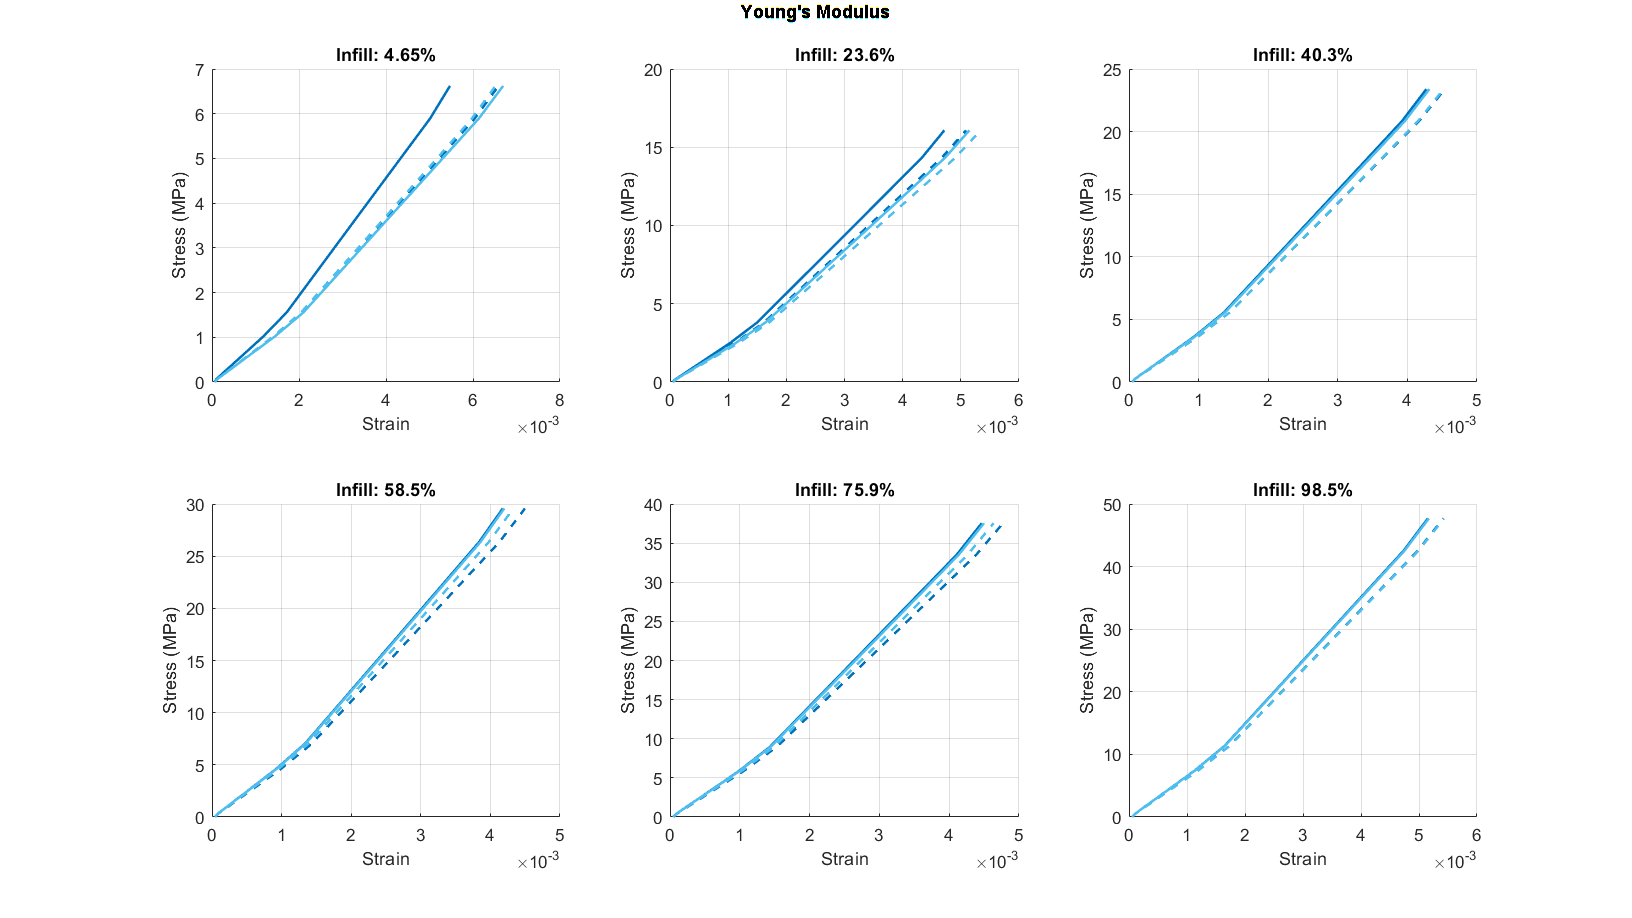

Illegal use of reserved keyword "end".

strain_y_mean = resultStruct.strain.strain_y_mean;
strain_y_median = resultStruct.strain.strain_y_median;
strain_z_mean = resultStruct.strain.strain_z_mean;
strain_z_median = resultStruct.strain.strain_z_median;
stress = resultStruct.stress;

figure(fig10);

if figureTitles
    gtitle('Young''s Modulus')
end

subplot(nRows, nCols, count);
title(sprintf('Infill: %.3g%%',resultStruct.infill_percentage));

hold on; grid on;
plot(abs(strain_y_mean),stress,'-','Color',blue, 'LineWidth', 1.5);
plot(abs(strain_y_median),stress,'--','Color',blue, 'LineWidth', 1.5);
plot(abs(strain_z_mean),stress,'-','Color',cyan, 'LineWidth', 1.5);
plot(abs(strain_z_median),stress,'--','Color',cyan, 'LineWidth', 1.5);


% legend('Mean Young''s Modulus xy', 'Median Young''s Modulus xy', 'Mean Young''s Modulus xz', 'Median Young''s Modulus xz','Location','best');

xlabel("Strain", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
ylabel("Stress (MPa)", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
drawnow;

count = count + 1;
end

savePath = fullfile(defaultFolder,'!Summary');

[status, msg, msgID] = mkdir(savePath);
if ~status
    error('Failed to create directory: %s', msg);
end

saveFigures(savePath,true,0);